# Introduction to the assets and their methods

Assets describe the objects and lights that are used in a PBRT scene.  The assets are read into ISET3d and stored in a slot within the rendering **recipe, **often** thisR.assets**.

The assets slot is a Matlab **tree** class.  The tree consists of a cell array of nodes, each with a unique name, and a vector of integers that specifies the parent node for every node.  The tree class has many methods that can be invoked, say **thisR.assets.print**;

The nodes of the asset tree, like any tree, can be thought of as the tree branches and leaves.  The nodes that are **branches** represent information about the position, orientation, and scale of the assets.  These properties are transmitted to all of the nodes below the branch. The nodes that are **leaves** define the shape and material properties of the assets.

This tutorial illustrates how to work with assets including how they are specified, how to find them, and how to edit them.  It uses some of the many methods that can be applied to the tree.  Programming the asset properties should make it easier for you to think.  The interface is intended to make programming the assets close to writing simple sentences.  Much of the programming will consist of set and get commands that apply to the assets. These have the form 

or

ISET3d Methods illustrated here include

**See also **

    t_assetsMotion.m, t_materials.m

## A simple scene

This simple scene has about 25 objects.  Some of the assets have long names. The nodes with figure_3m in the name refer to a blue stick figure at 3 meter distance from the camera.  The ones with figure_6m define a yellow stick figure at 6m distance from the camera.  Here is a low resolution rendering of the scene.  

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 6 materials
Read 1 textures
Reading C4D geometry information.



% We set a low resolution for speed.
thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5);

piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


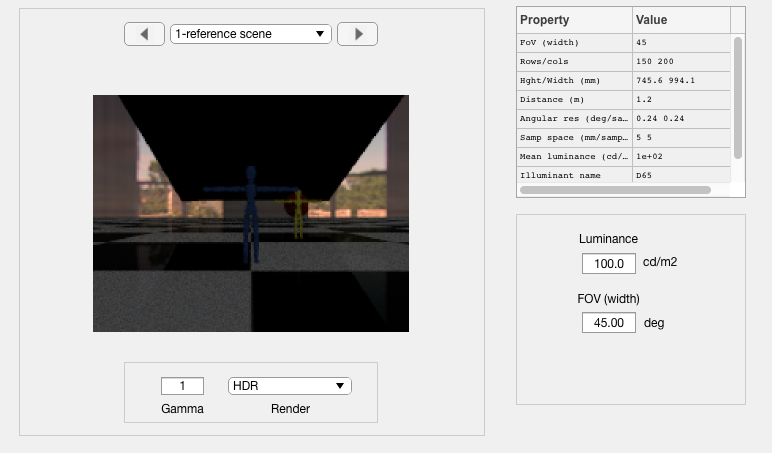

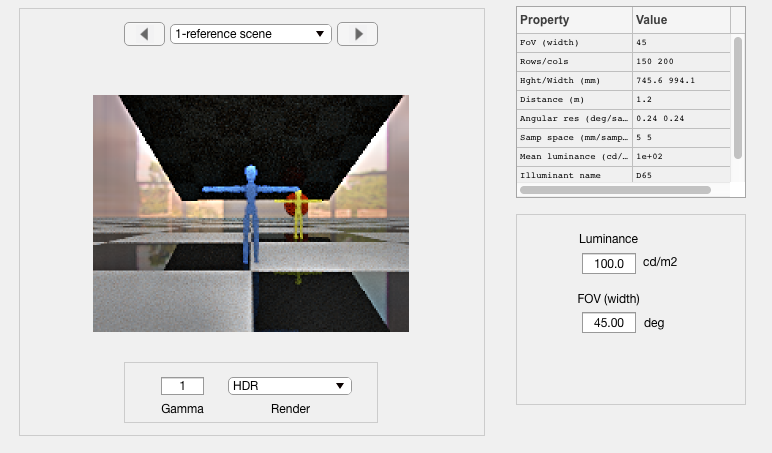

scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## The asset tree

The variable **thisR **is the rendering recipe.  It contains a slot for the assets tree.  We have implemented a couple of methods for displaying the tree, either in a figure or printed to the command window.

% Simple tree
thisR.assets

ans =   tree with properties:

      Node: {26×1 cell}
    Parent: [26×1 double]


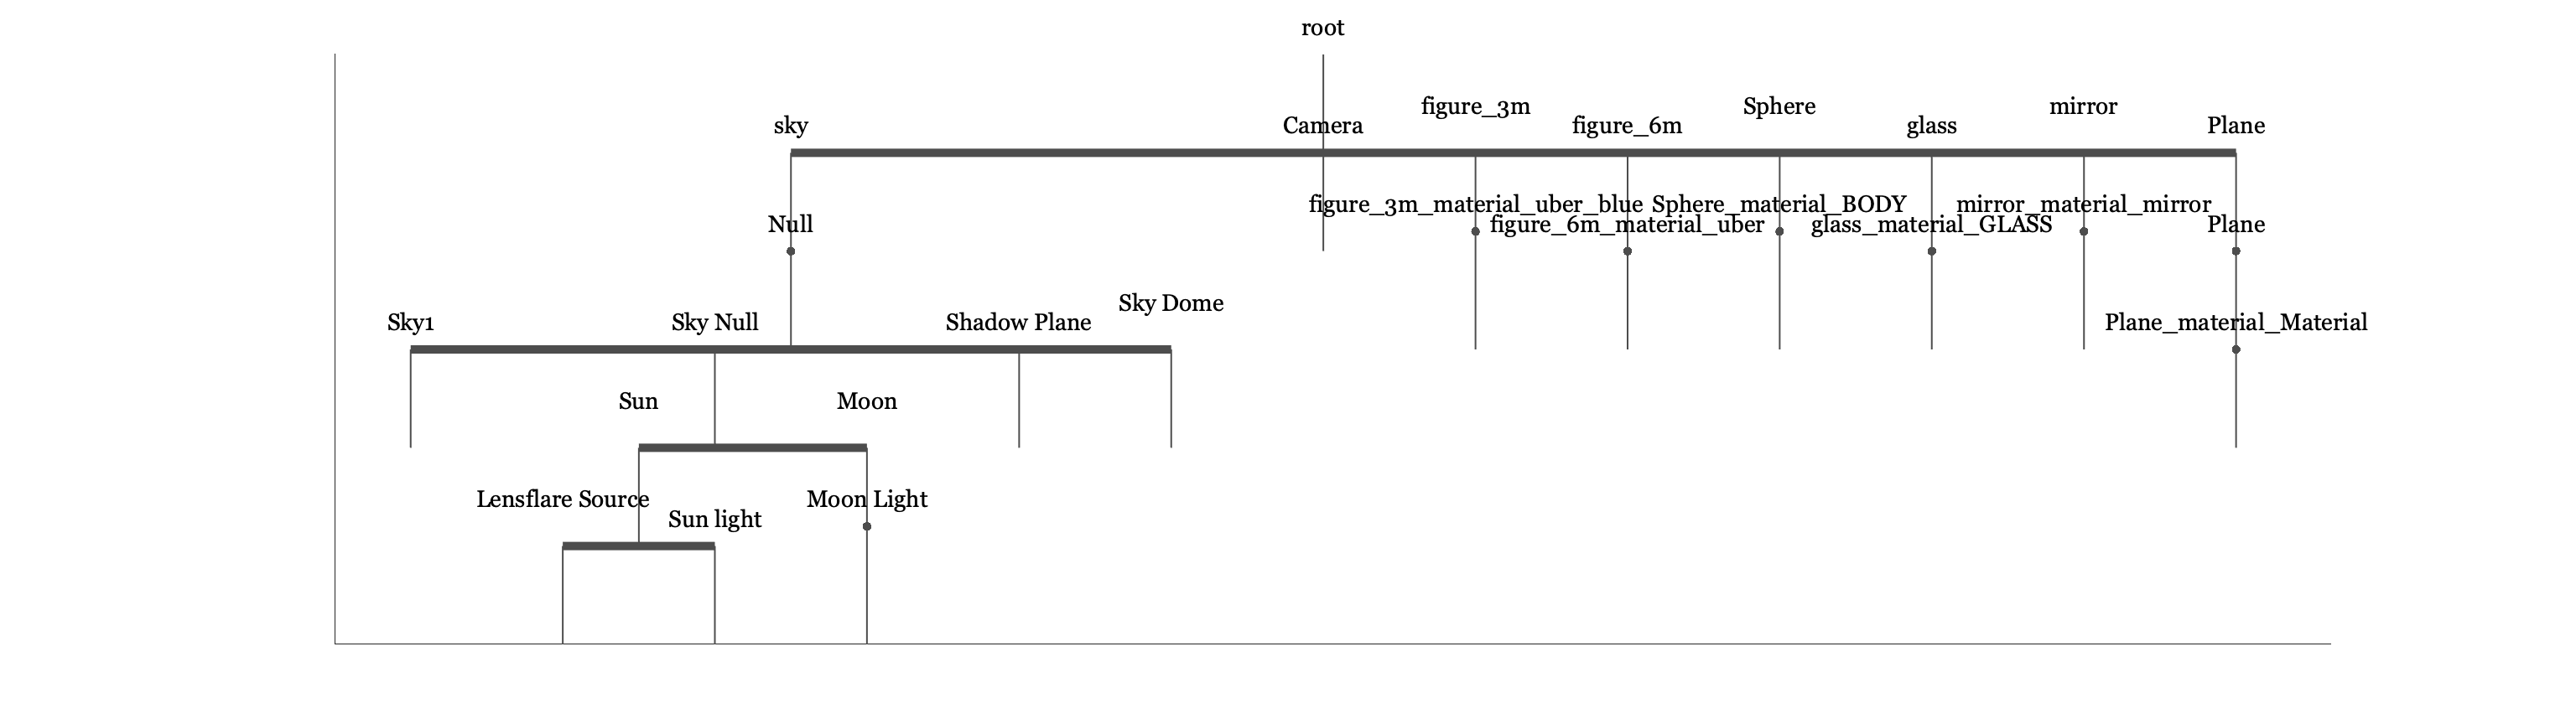


% You can display the asset tree structure in a figure.
thisR.assets.show;


% You can print the asset tree structure in the command window
thisR.assets.print;

                                                                                                         001ID_root                                                                                                          
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                              002ID_sky                                                 013ID_Camera    014ID_fi..re_3m  016ID_fi..re_6m   018ID_Sphere      020ID_glass     022ID_mirror      024ID_Plane   
                                                                                                                

## Example tree methods 

There are many tree methods that can be applied to the assets.  Here are just a few examples.

## How to get an asset

The number of available **recipe** 'get' commands is large and growing.  The get commands related to assets start with the 'asset' string.  Here are some examples.

% You can request and asset by its name. 
thisR.get('asset','002ID_sky')

ans = struct with fields:
        type: 'branch'
        name: '002ID_sky'
        size: [1×1 struct]
       scale: [1 1 1]
    position: [0 0 0]
      rotate: [4×3 double]
      motion: []



% The ID will be returned.
thisR.get('asset id','002ID_sky')

ans = 2


% The parent of the asset
thisR.get('asset parent','002ID_sky')

ans = '001ID_root'


% Use the node number to get the whole struct
thisR.assets.get(2)

ans = struct with fields:
        type: 'branch'
        name: '002ID_sky'
        size: [1×1 struct]
       scale: [1 1 1]
    position: [0 0 0]
      rotate: [4×3 double]
      motion: []



% An asset property 
thisR.get('asset','sky','position')

ans =      0     0     0


thisR.get('asset','sky','scale')

ans =      1     1     1


## Rotate the blue man

The point of this implementation is to make it easy to do things like change the position, orientation or other properties of an asset.  Here is the first example.  

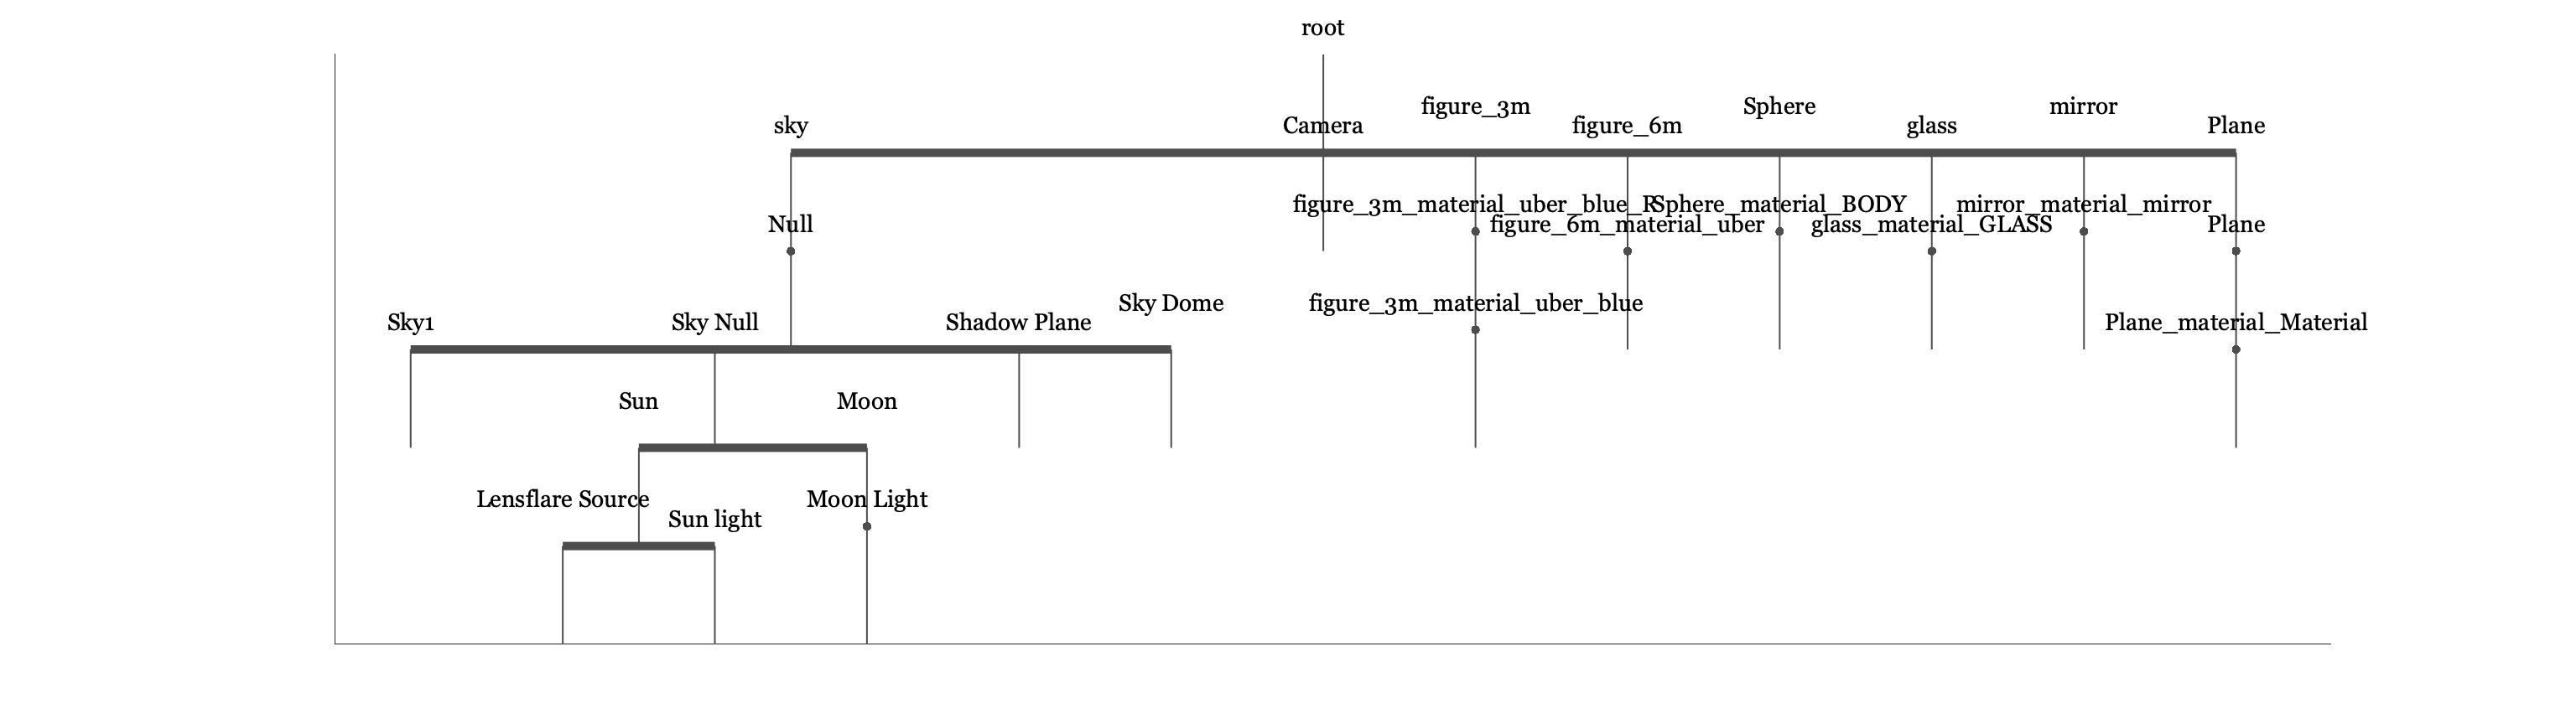

% This asset is the leaf of the blue man
assetName = 'figure_3m_material_uber_blue'; 

% This places a new branch node representating a rotation just above the
% named leaf asset.  The rotation is (x,y,z) in degrees.  We are rotating
% around the z-axis in this case.
rotateBranch = thisR.set('asset', assetName, 'rotate', [0, 0, 45]);

% Notice that there is a new node just above the 015ID_ asset.
thisR.assets.show;

## Write and render

piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


scene = sceneSet(scene, 'name', 'Rotation');
sceneWindow(scene);

**Note**:  the command

will eliminate the rotation branch and return the blue man to upright

## Translate

% This is the object representing the yellow man
assetName = 'figure_6m_material_uber';

% In this example, we find the branch node that is just above the yellow
% man, representing its position, rotation and such.
thisAsset = thisR.get('asset parent id',assetName);

% We add a translation, moving yellow man 2 meters in the z direction.
translateBranch = thisR.set('asset', thisAsset, 'translate', [0, 0, -2]);

% This time the new branch is below the branch, but above the object (leaf)
% that contains the object shape.
thisR.assets.print;

                                                                                                         001ID_root                                                                                                          
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                              002ID_sky                                                 013ID_Camera    014ID_fi..re_3m  016ID_fi..re_6m   018ID_Sphere      020ID_glass     022ID_mirror      024ID_Plane   
                                                                                                                


piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 



scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


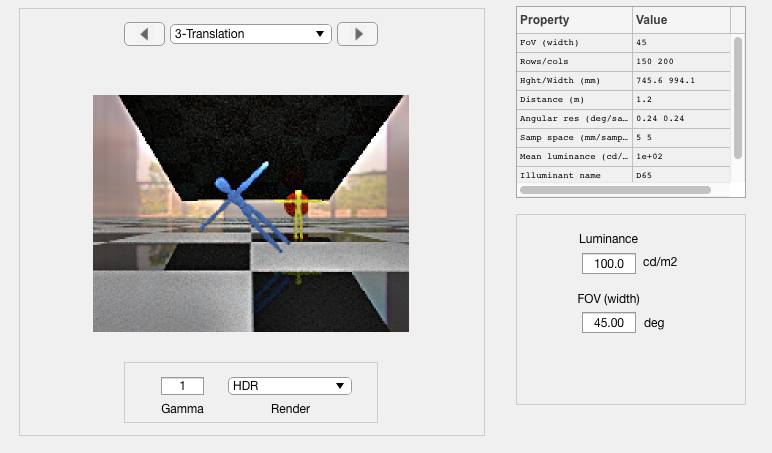

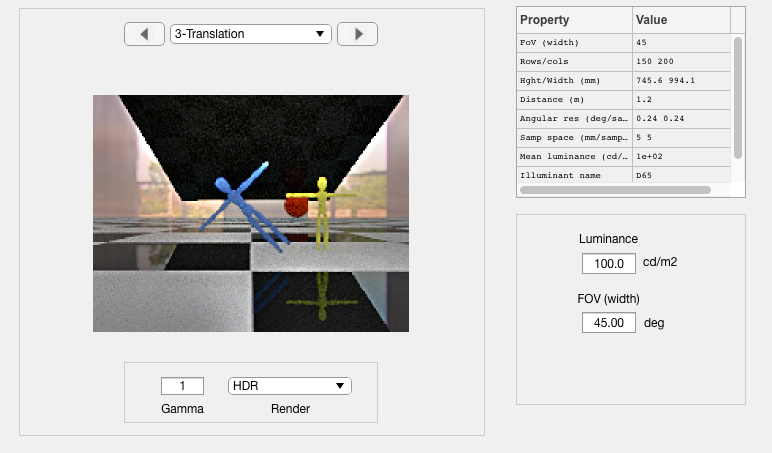

scene = sceneSet(scene, 'name', 'Translation');
sceneWindow(scene);

## Scale

% This is the object representing the yellow man
assetName = 'figure_6m_material_uber';

% We scale the size of the yellow man
scaleBranch = thisR.set('asset', assetName, 'scale', 1.2);

% This time the new branch is below the branch, but above the object (leaf)
% that contains the object shape.
thisR.assets.show;

piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 



scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


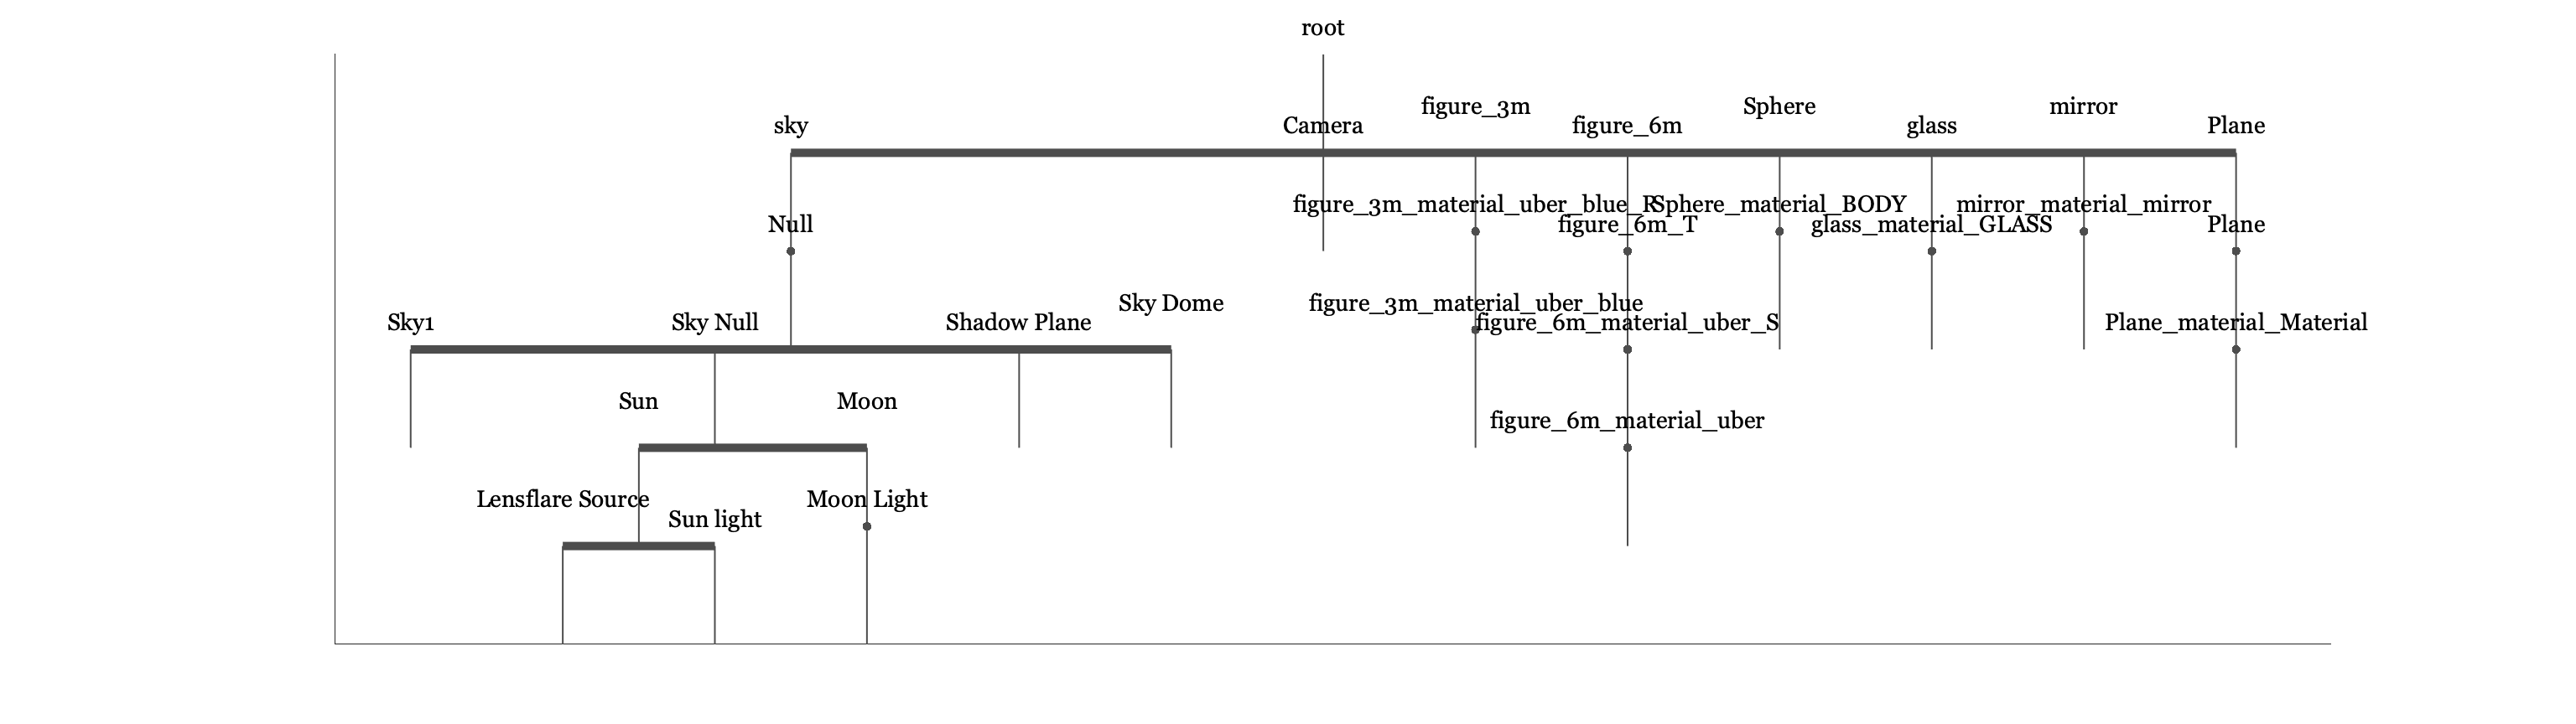

scene = sceneSet(scene, 'name', 'Translation');
sceneWindow(scene);

## Add an object

% The blue man.
thisAsset = 'figure_3m_material_uber_blue'; 

% Get the blue man that we will modify into a new asset.
newAsset = thisR.get('asset',thisAsset);
newAsset.name = 'blueGuy2';

% We add the asset below the parent of the current blue man. 
parent = thisR.get('asset parent',thisAsset);     % The parent

% Calls the function to insert an asset below a parent.
thisR.set('asset',parent.name,'add',newAsset);    

thisR.assets.print;

                                                                                                                 001ID_root                                                                                                                   
                                                  +-----------------------------------------------------------+-------+----------------+-------------------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                        |                         |                |                |                |                |        
                                              002ID_sky                                                 013ID_Camera            014ID_fi..re_3m           016ID_fi..re_6m   018ID_Sphere      020ID_glass     022ID_mirror      024ID_Plane   
                                            


thisR.set('asset',newAsset.name,'rotate',[0 0 -45]);
thisR.set('asset',newAsset.name,'translate',[1 0 0]);
thisR.assets.print;

                                                                                                                 001ID_root                                                                                                                   
                                                  +-----------------------------------------------------------+-------+----------------+-------------------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                        |                         |                |                |                |                |        
                                              002ID_sky                                                 013ID_Camera            014ID_fi..re_3m           016ID_fi..re_6m   018ID_Sphere      020ID_glass     022ID_mirror      024ID_Plane   
                                            


piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


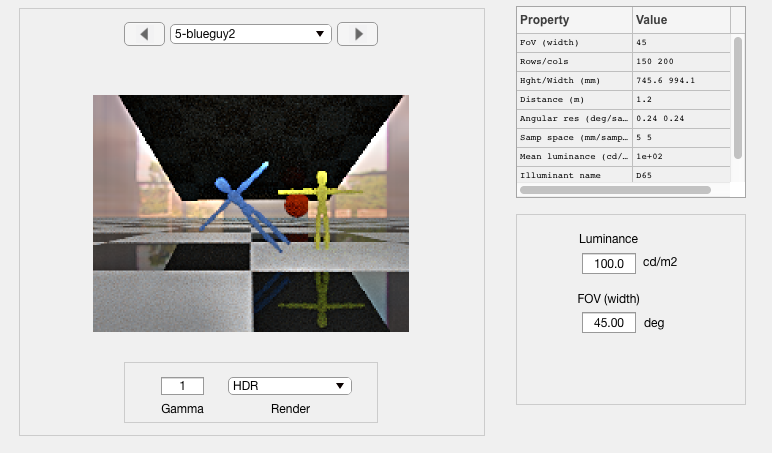

scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);

## Delete an object

thisAsset = 'figure_3m_material_uber_blue'; 
thisR.set('asset',thisAsset,'delete');
thisR.assets.print;

                                                                                                         001ID_root                                                                                                          
                                                  +----------------------------------------------------------++----------------+----------------+----------------+----------------+----------------+----------------+        
                                                  |                                                           |                |                |                |                |                |                |        
                                              002ID_sky                                                 013ID_Camera    014ID_fi..re_3m  016ID_fi..re_6m   018ID_Sphere      020ID_glass     022ID_mirror      024ID_Plane   
                                                                                                                


piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


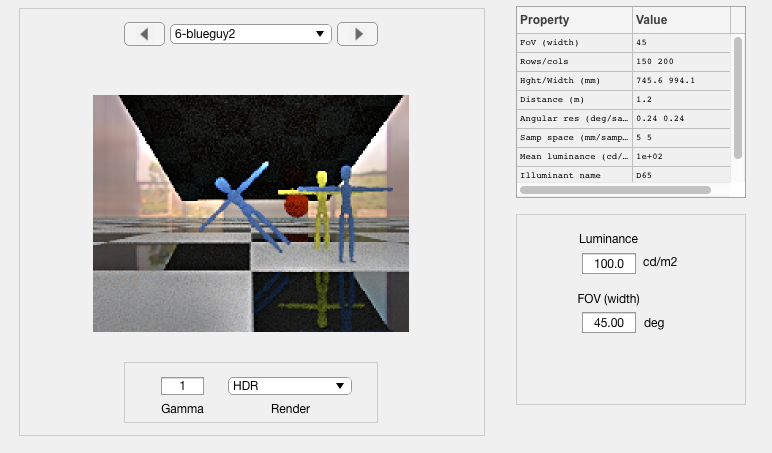

scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);

## Delete a translate node

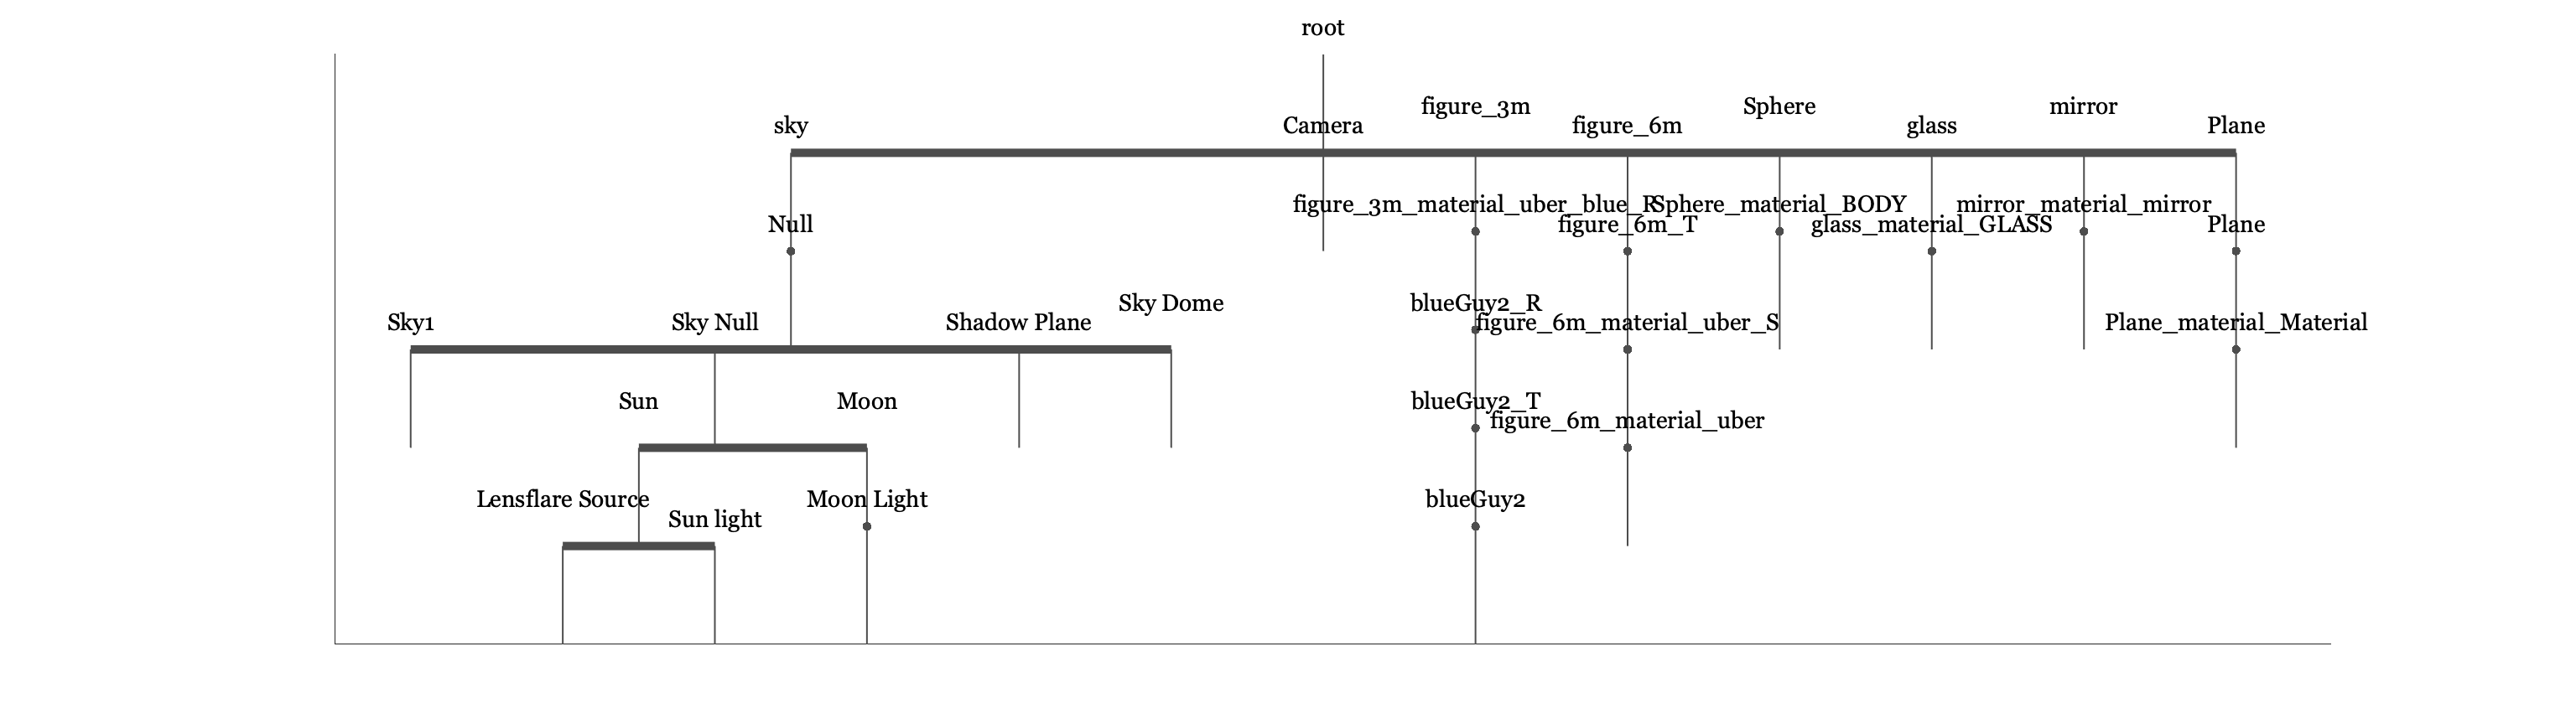

thisR.assets.show;

assetName = 'blueGuy2'; 
parentID = thisR.get('asset parent id',assetName);
thisR.set('asset',parentID,'delete');

piWrite(thisR);

Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/environment_Reflection.exr
Copying /Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene/room.exr
Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d/data/V3/SimpleScene 
to 
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene 
 
Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Material file SimpleScene_materials.pbrt written successfully.
/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene_geometry.pbrt is written out 


[scene, results] = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  2.7 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.
  Read 930000 pixel elements for image.


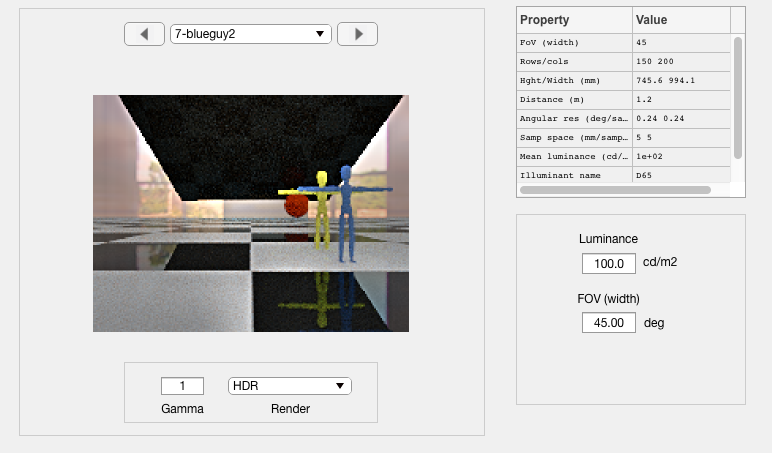

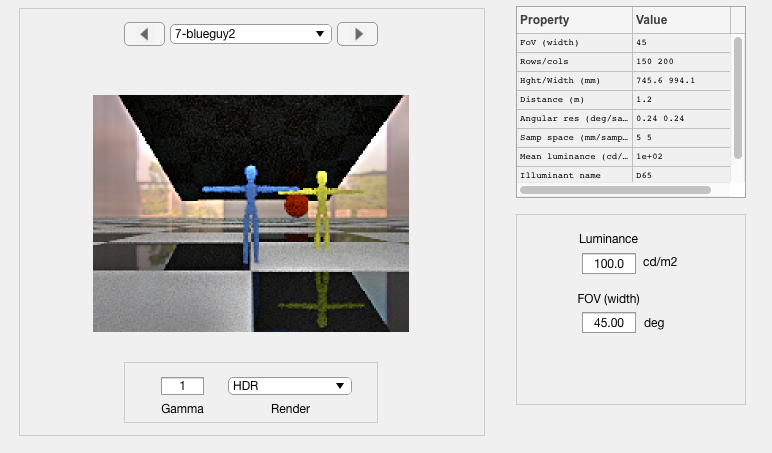

scene = sceneSet(scene, 'name', 'blueguy2');
sceneWindow(scene);